# VLP Simulations

This file performs the simulations for the following controllers to generate results for the thesis:

- The VNHC $l^\star(\theta)$ which corresponds to the time-optimal controller from the paper "Pumping a swing by standing and squatting".

- The VNHC $l(\theta) = -\Delta l \sin(2\theta) + l_\text{avg}$ which is the smooth version of $l^\star(\theta)$.

Simulate both the smooth controller and the optimal controller using the average height of a 25-year old Estonian who is Kiiking. We use the longest ever Kiiking swing (7.38m) and we know the average height of a 25-year old Estonian man is 180cm. If their squat height is 90cm and the COM is always half their height, we get $\underline{l} = 6.48$ and $\bar{l}=6.93$.

Second, we pick a few $\delta > 0$ small and generate $N$ trials where we initialize the acrobot inside the set $E_\text{avg}(\delta,0)$. Track how long it takes each controller to start rotating (i.e. to reach $E_\text{avg}(\pi,0)$) and tabulate these results.

clear all;
close all;
clc;

% Set the swing height, person height, person weight
swingl = 3;%7.38; % m
personl = 1.8; % m
personkg = 80.17; % kg
personstandl = personl/2; % com is at half the person height
personsquatl = personl/4; % squat is half of that

% Set the dynamic variables of the vlp
m = personkg;
g = 9.81;
lu = swingl - personstandl;
lb = swingl - personsquatl;
lavg = (lu + lb)/2;

% Set the T-value for L_T(theta)
lT = 0.01;

% Set the symbolic variables
q = sym('q','real');
p = sym('p','real');
l = sym('l','real');
% Define the energy
E = p^2/(2*m*l^2) + m*g*l*(1 - cos(q));
Eavg = subs(E,l,lavg);
Eavgf = matlabFunction(Eavg,'vars',[q p]);
% Get the dynamics
qd = simplify(diff(E,p));
pd = simplify(-diff(E,q));
eom = matlabFunction([qd; pd],'vars',[q p l]);

% Define the optimal controller
eom_opt = @(q,p)eom(wrapToPi(q),p,...
    vlp_l_optimal_gain(atan2(p,q),lu,lb));
% Define the differentiable controller
eom_diff = @(q,p)eom(wrapToPi(q),p,...
    vlp_l_T(atan2(p,q),lu,lb,lT));
% Define the smooth controller
eom_smooth = @(q,p)eom(wrapToPi(q),p,...
    vlp_l_smooth(atan2(p,q),lu,lb));

% Set the simulation time
T = 4700;

% Set the initial condition for simulation
q0 = pi/32;
x0 = [q0;0];

% Set the base options for the simulation
% Trigger an event when qu = pi
baseOptions = odeset('AbsTol',10e-14,'RelTol',10e-14,...
    'Events',@rotationEvent);

## Part 1: Simulate a Person

We simulate this VLP starting at $q = \frac{\pi}{32}$ and display the orbit of both , superimposed. Also display the anti-Lyapunov function $E_\text{avg}(q,p) = \frac{p^2}{2ml_\text{avg}^2} + (1-mgl_\text{avg}cos(\theta))$.

% Simulate the two controllers
solopt = ode45(@(t,x)eom_opt(x(1),x(2)),...
    [0,T],...
    x0,...
    baseOptions);
soldiff = ode45(@(t,x)eom_diff(x(1),x(2)),...
    [0,T],...
    x0,...
    baseOptions);
solsmooth = ode45(@(t,x)eom_smooth(x(1),x(2)),...
    [0,T],...
    x0,...
    baseOptions);

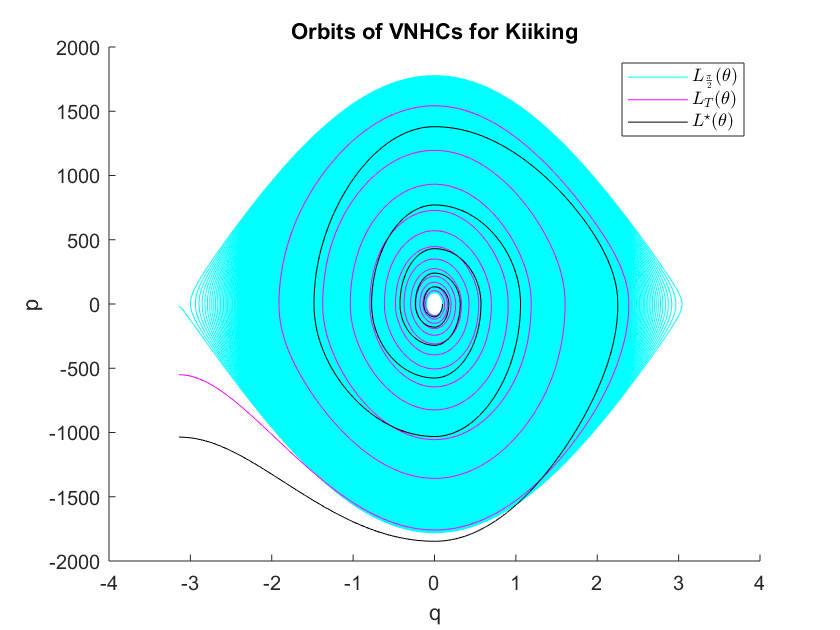

% Display them together
orbitfig = figure;
hold on;
plot(solsmooth.y(1,:),solsmooth.y(2,:),'c');
plot(soldiff.y(1,:),soldiff.y(2,:),'m');
plot(solopt.y(1,:),solopt.y(2,:),'k');
hold off;
title('Orbits of VNHCs for Kiiking');
xlabel('q');
ylabel('p');
legend({'$L_\frac{\pi}{2}(\theta)$',...
         '$L_T(\theta)$',...
         '$L^\star(\theta)$'},...
         'interpreter','latex');
% Save it
saveas(orbitfig,'images/kiiking_orbits','png');

saveas(orbitfig,'images/kiiking_orbits','fig');

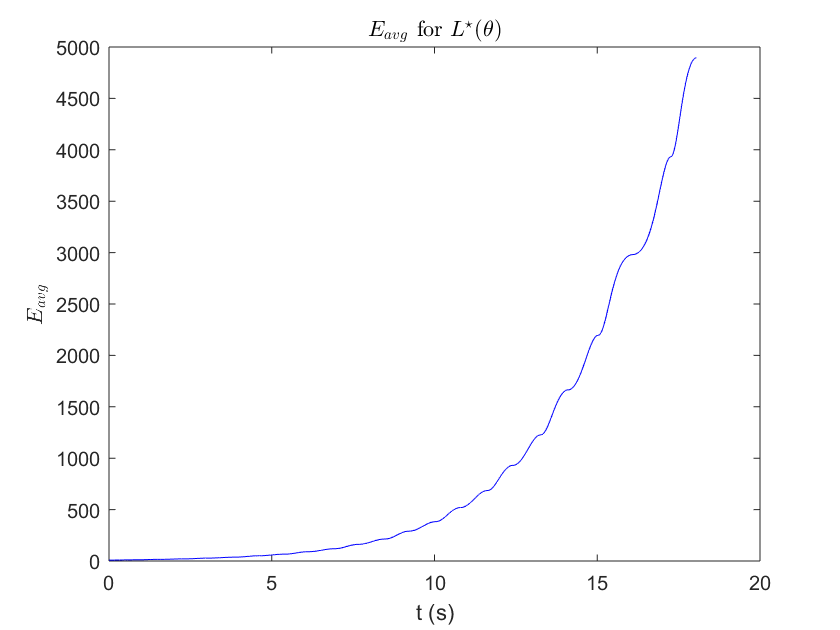

% Show the energy function for the optimal solution
Eoptfig = figure;
plot(solopt.x,Eavgf(solopt.y(1,:),solopt.y(2,:)),'b');
title('$E_{avg}$ for $L^\star(\theta)$',...
    'Interpreter','latex');
xlabel('t (s)');
ylabel('$E_{{avg}}$','Interpreter','latex');
saveas(Eoptfig,'images/E_kiiking_lstar','fig');
saveas(Eoptfig,'images/E_kiiking_lstar','png');

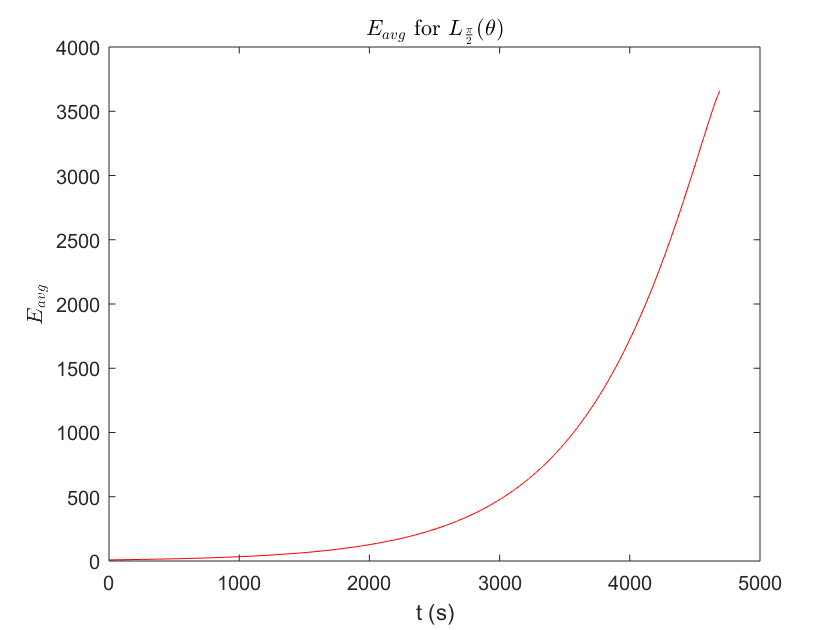


% Show the energy for the smoothed VNHC
Esmoothfig = figure;
plot(solsmooth.x,Eavgf(solsmooth.y(1,:),solsmooth.y(2,:)),'r');
title('$E_{avg}$ for $L_\frac{\pi}{2}(\theta)$',...
    'interpreter','latex');
xlabel('t (s)');
ylabel('$E_{avg}$','Interpreter','latex');
saveas(Esmoothfig,'images/E_kiiking_ltheta','fig');
saveas(Esmoothfig,'images/E_kiiking_ltheta','png');